We are glad you are using our code. We will be happy to receive your feedback and help you if needed. If necessary, please contact us at szaksz@mm.bme.hu or at habib@mm.bme.hu. This code is provided freely for scientific purposes, and while not mandatory, we would greatly appreciate if users could acknowledge its use by citing our paper: Szaksz, B., Stepan, G., & Habib, G. (2024). Dynamical integrity estimation in time delayed systems: a rapid iterative algorithm. Journal of Sound and Vibration, 571, 118045.

This is an example code to show, how the algorithm can estimate the local integrity measure (LIM) of a delayed Duffing oscillator.

clear
close all
% clc
set(0,'defaulttextinterpreter','latex')
set(0, 'DefaultLegendInterpreter', 'latex')
set(groot, 'DefaultAxesTickLabelInterpreter', 'latex')

Parameter values for the system and for the computation.

% parameter values
a = 1;
zeta = 0.1;
tau = 0.1;
% the equation of motion is x''+2*zeta*x'-x(t-taudl)-a*x^3=0

% time discretization within the semi-discretization
r = 30;      % sampling delay number
dt = tau/(r+1/2);  % time step

% construction of the structure of parameters
par = struct('r',r,'dt',dt,'tau',tau); % these parameters are needed for 
par.a = a;
par.zeta = zeta;

% equilibrium point
xe=[-(1/par.a)^0.5,0];

% variable of the phase space to be plot (unnecessary for this system,
% since it has only 1 DoF)
var1=1;
var2=2;

% number of step of the iteration
number_of_steps=50;

% space boundary
spaceboundary=[-4,-4,4,4];    % space within the simulations are run i.e.: ([-q1,-dq1,q1,dq1])

% discretization of the phase space in each direction
discr=501;

% figure number
numfig = 103;

Computation of the matrices, determined by semi-discretization. These are later used in the time-integration of the solutions. The weights are also determined, with which the disctance in the phase space is computed. The first term correspond to the natural frequency squared. For more information about the underlying logic of the algorithm, please look at our paper Dynamical integrity estimation in time delayed systems: a rapid iterative algorithm.

[par,weight] = dyn_Duffing(par);  % the dynamics of the system

Computation of the Local Integrity Measure (LIM) of the system 

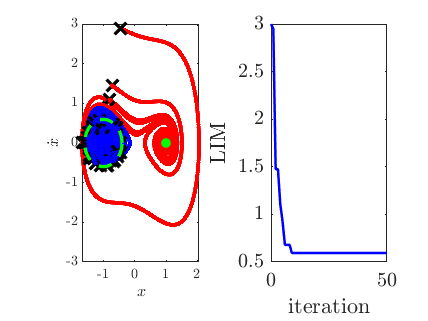

figure(numfig);
subplot(1,2,1)

% computation of the LIM. Initial conditions selected as free vibration solutions (init_type=3)

[R_final,OutL,OutH]=compute_LIM_D_FP_HIC(xe,par,'weight',weight, ...
        'var1',1,'var2',2,'plot_results',1,'plot_results_final',0,'automatic',0,...
        'number_of_steps',number_of_steps,'spaceboundary',spaceboundary,'discr',discr,...
        'rep_fix_point',100,'rep_periodic',50,'num_of_cell_around_equilibrium',3,...
        'num_fig',numfig,'init_type',3);
xlabel('$x$')
ylabel('$\dot{x}$')
title('')
% plot circle representing the LIM
LIM_phi = linspace(0,2*pi,1000);
LIM_r = (R_final^2./(weight(1)*cos(LIM_phi).^2+sin(LIM_phi).^2)).^0.5;
figure(numfig);
subplot(1,2,1)
hold on
plot(OutL.x0(1,1),OutL.x0(1,2),'kx','LineWidth',2,'MarkerSize',10)
plot(1,0,'g.','MarkerSize',20)
plot(OutL.xe(1)+LIM_r.*cos(LIM_phi),OutL.xe(2)+LIM_r.*sin(LIM_phi),'--','color','g','LineWidth',2)
% plot the estimated value of LIM during the iteration
subplot(1,2,2)
plot([0:1:length(OutL.R)-1],OutL.R,'b','Linewidth',1.5)
xlabel('iteration')
ylabel('LIM')
set(gca,'FontSize',12)